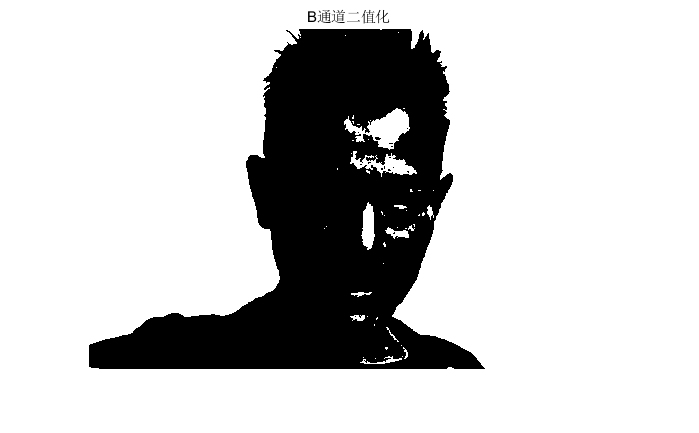

clc;
clear;
I=imread('03-刘德华.jpg');
background=imread('03-大海背景.jpg');
%由于天空蓝色分量较大，故对图像B通道做二值化
I_bin=imbinarize(I(:,:,3));
figure()
imshow(I_bin)
title("B通道二值化")

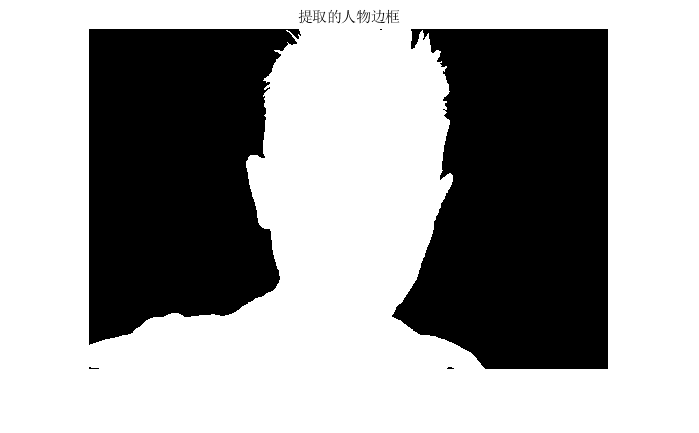

%图像反转
I_revert=1-I_bin;
%孔洞填充
I_deli=imfill(I_revert,8);
figure()
imshow(I_deli)
title("提取的人物边框")

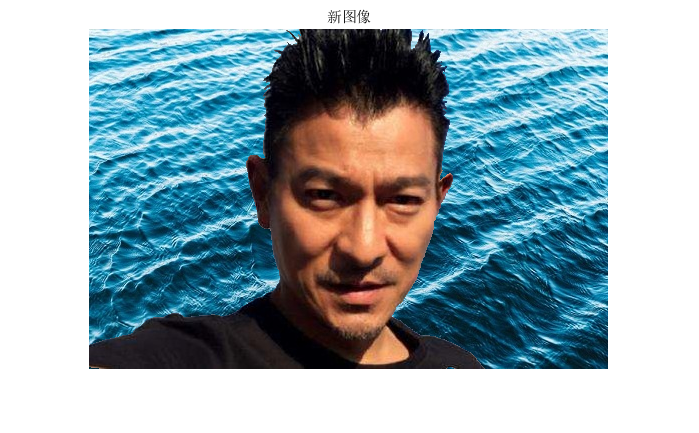

%将人物和新的背景合成
I=I.*uint8(repmat(I_deli,[1,1,3]))+background.*uint8(repmat(1-I_deli,[1,1,3]));
figure()
imshow(I);
title("新图像")